# Example 4.4: Estimation for Exponential using MLE

Note: this script reproduces Example 4.4 (Section 4.2) of **Statistics for Chemical Engineers**: maximum likelihood estimation of the parameter of Exp(2). Victor Z UW-Madison, 2019 MLE for exponential RV

clc; clear all; close all hidden;

## Data

generate observations for weibull

rng(0)
S = 1000;
x = exprnd(2,S,1);

## Log-likelihood

plot log likelihood

beta=linspace(0,10,100);
ss=sum(x)

ss =    2.0051e+03

logL=-S*log(beta)-(1./beta)*ss;

## Estimate

estimate

betahat=mean(x)

betahat =    2.0051e+00

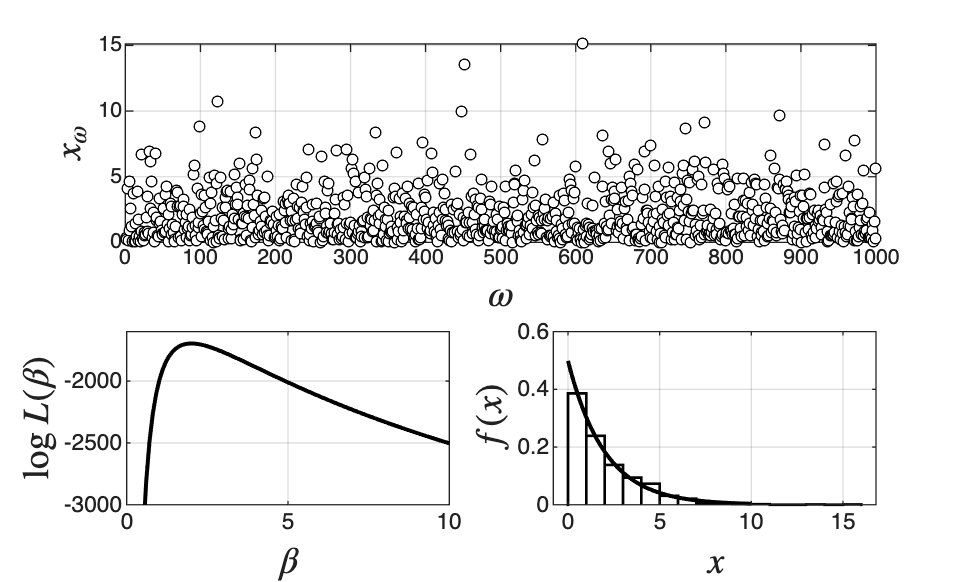


figure(1)
subplot(2,2,[1 2])
plot(x,'blacko','MarkerFaceColor','w','MarkerSize',4)
xlabel('$\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_\omega$','Interpreter','latex','FontSize',14)
grid on
subplot(2,2,3)
plot(beta,logL,'black-','LineWidth',1.5)
xlabel('$\beta$','Interpreter','latex','FontSize',14) 
ylabel('$\log L(\beta)$','Interpreter','latex','FontSize',14) 
grid on
axis([0,10,-3e3, -1.6e3])
subplot(2,2,4)
xgrid=linspace(0,10,100);
histogram(x,'BinWidth',1,'Normalization','pdf','EdgeColor','black','FaceColor','none','LineWidth',1)
hold on
plot(xgrid,exppdf(xgrid,betahat),'black-','LineWidth',1.5);
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
grid on
print -depsc ch4_loglike_exp.eps

## Note

As in the book, the likelihood is a product of many small numbers (about 0.3^1000), which is numerically zero: this is why we maximize the log-likelihood.